# Aula 3, 4:

## Análise em frequencia, FT no tempo, FT na frequencia, Resposta ao impulso:

O objetivo aqui será obter a função de transferencia de um sistema discretizado a partir do sistema contínuo (em estado de espaços), a partir de uma série de manipulações e transformações, e comparar o resultado com a transformada Z do sistema gerada pelo matlab: 

SysC = tf(0.5, [1 2 2]);
SysD = c2d(ss(SysC), 0.1);
phi = SysD.A;
gama = SysD.B;

Vamos então obter a Função de Transferência no Tempo dessa função:

Hz = SysD.C*((sym('z')*eye(2) - phi)\gama);
disp(vpa(Hz, 3));

$$\frac{12.8\,\left(4.76e+29\,z+4.45e+29\right)}{2.6e+33\,z^{2}-4.67e+33\,z+2.13e+33}$$

Uma vez que Hq é uma expressão simbólica, grande e feia, vamos simplifica-la na força bruta:

Hz = (0.005*2.43/5.19*sym('z')+0.005*2.27/5.19)/(sym('z')^2-9.4/5.19*sym('z')+4.25/5.19);
disp(vpa(Hz, 3))

$$\frac{0.00234\,z+0.00219}{z^{2}-1.81\,z+0.819}$$

Agora, vejamos o valor da função de transferencia gerada pelo Matlab:

HzMat=tf(SysD);
HzMat


HzMat =
 
  0.002337 z + 0.002187
  ----------------------
  z^2 - 1.801 z + 0.8187
 
Sample time: 0.1 seconds
Discrete-time transfer function.



Como esperado, obtivemos a exata mesma expressão. 

## Análise de Estabilidade:

Agora, vamos encontrar os polos e analisar a estabilidade dos sistemas, a começar pelo contínuo: 

Pc = pole(SysC)

Pc =   -1.0000 + 1.0000i
  -1.0000 - 1.0000i


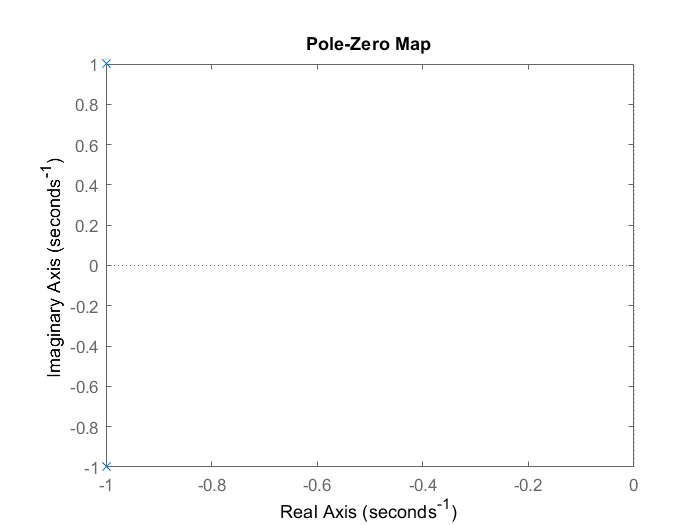

pzmap(SysC)

De fato, o sistema é, portanto, estável:

isstable(SysC)

ans = logical
   1


Agora, para o sistema discreto 

Pd = pole(SysD)

Pd =    0.9003 + 0.0903i
   0.9003 - 0.0903i


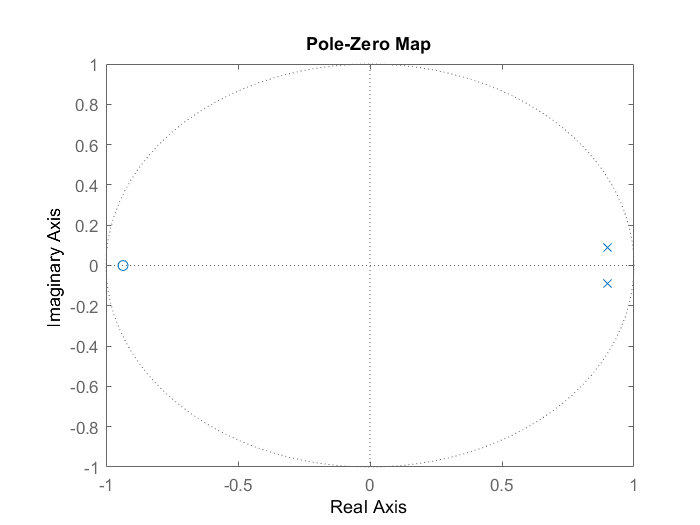

pzmap(SysD)

isstable(SysD)

ans = logical
   1


O critério de estabilidade então muda, mas o sistema, bem discretizado, permanece estável;